clear

## Run other scripts

% DATA_TYPE = 'lowSI'; % or 'highSI'
DATA_TYPE = 'lowSI';


## Load the data

MODEL = 'ESN';

if strcmp(DATA_TYPE,'highSI')
    data_real = readmatrix(strcat('..\Data\',MODEL,'\real_data_39_highSI.txt'));
else
    data_real = readmatrix(strcat('..\Data\',MODEL,'\real_data_39_lowSI.txt'));
end

data_real = data_real(1:5:end);

## Fit the data to the gamma-gamma distribution

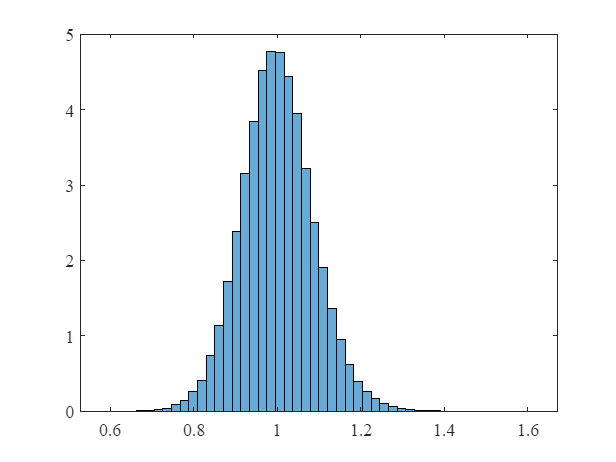

histo = histogram(data_real, 50, 'Normalization','pdf');

## Log-normal pdf

pdf_ln_fit = @(sigma_r, h_a) 1 ./ (sqrt(2*pi) .* sigma_r .* h_a) ...
            .* exp(- (log(h_a) + sigma_r.^2 ./2).^2 ./ (2 .* sigma_r.^2));
%% Histogram and fit the data
p_ln = lognfit(data_real);

Rytov = p_ln(2);

Rytov;

## Plot the fit line

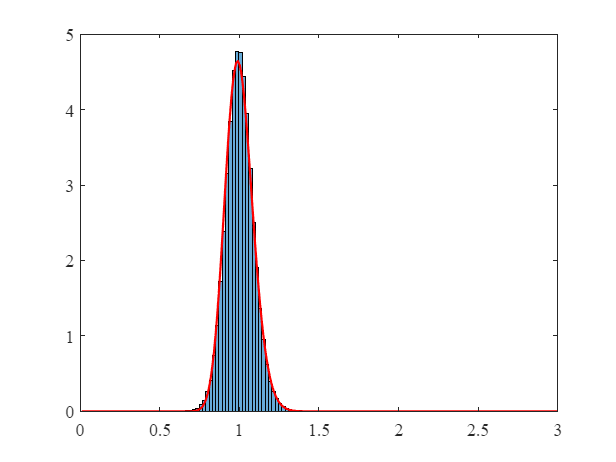

hold on
x = 0:0.01:3;
y2 = pdf_ln_fit(Rytov,x);
% plot(x,y,'r','LineWidth',1.5);
plot(x,y2,'r','LineWidth',1.5);
hold off
xlim([0 3]);

outsize = 7;

Parameters_delay;

Model_Atmospheric_turbulence;

Model_AMP;

P_t = 1.9934

E_b_anal = 9.9999e+05

EE_anal = 5.0164e+08


% Model_Channel_state_thes;

if strcmp(DATA_TYPE, 'lowSI')
    load Workspace\Channel_state_thres_var\lowSI_fc=55.7.mat;
else
    load Workspace\Channel_state_thres_var\highSI_fc=55.7.mat;
end

% h_state_thres = h_state_thres(1:3:end);
% N_state = length(h_state_thres)-1;

Model_Channel_state_assignment;

Model_AMP_subopt_state;

P_t = 1.9331

rate_anal = 9.6984e+08

EE_anal = 5.0171e+08

for j = 1:outsize

    Data_Proc_Import_data;

    Model_AMP_subopt_state_predicted;
    
    count_SAMP(j) = count;
    
    EL_SAMP(j) = energy_loss;
    
    EE_SAMP(j) = EE_predicted;
end

energy_loss = 2.1280e-04

EE_predicted = 4.5371e+08

energy_loss = 3.1264e-04

EE_predicted = 4.2784e+08

energy_loss = 4.2304e-04

EE_predicted = 3.9928e+08

energy_loss = 5.1260e-04

EE_predicted = 3.7617e+08

energy_loss = 5.8588e-04

EE_predicted = 3.5732e+08

energy_loss = 6.4342e-04

EE_predicted = 3.4257e+08

energy_loss = 6.9001e-04

EE_predicted = 3.3066e+08

# Plot the figures

## Set global configurations

set(groot, 'defaultLineMarkerSize', 25);
set(groot, 'DefaultLineLineWidth', 2);
set(groot, 'defaultAxesFontName', 'TimesNewRoman');
set(groot, 'defaultTextFontName', 'TimesNewRoman');
set(groot, 'defaultAxesFontSize', 12);
set(groot, 'defaultTextFontSize', 12);

x_axis = 1:outsize;

# Low SI data type

if strcmp(DATA_TYPE, 'lowSI')

## Plot count

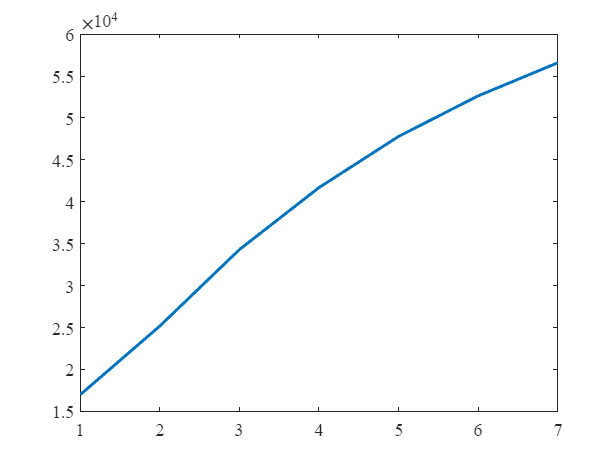

    y_axis = count_SAMP;
    plot(x_axis, y_axis)

## Plot EL

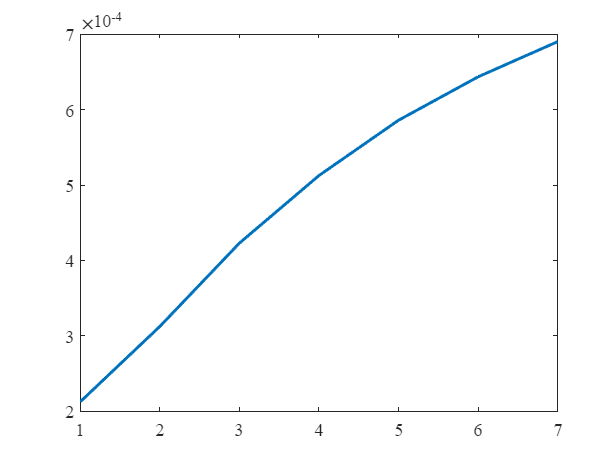

    y_axis = EL_SAMP;
    plot(x_axis, y_axis)

## Plot EE

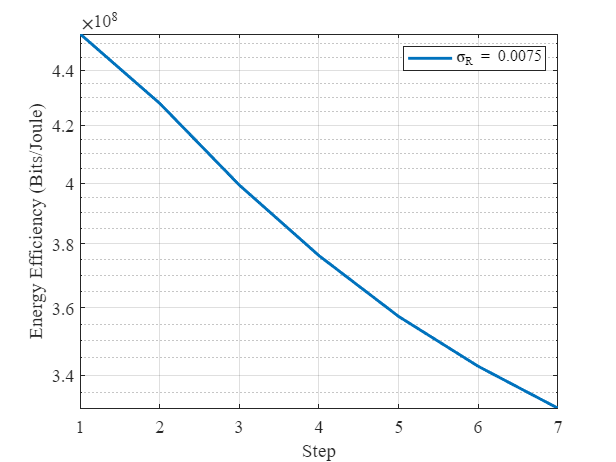

    y_axis = EE_SAMP;
    semilogy(x_axis, y_axis, 'DisplayName', '\sigma_{R} = 0.0075')
    xlabel('Step')
    ylabel('Energy Efficiency (Bits/Joule)')
    legend()
    grid on

end

# High SI data type

if strcmp(DATA_TYPE, 'highSI')

## Plot count

    y_axis = count_SAMP;
    plot(x_axis, y_axis)

## Plot EL

    y_axis = EL_SAMP;
    plot(x_axis, y_axis)

## Plot EE

    y_axis = EE_SAMP;
    semilogy(x_axis, y_axis, 'DisplayName', '\sigma_{R} = 0.1020')
    xlabel('Step')
    ylabel('Energy Efficiency (Bits/Joule)')
    legend()
    grid on

end

writematrix(EE_SAMP, 'Workspace/Results/EE-multi-step-lowSI.txt', Delimiter='\t')